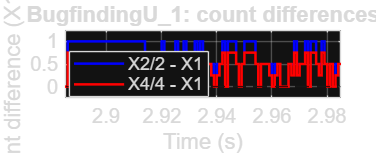

S = load('C:\Users\Admin\Desktop\RMX\Lab\encoder\data.mat');
name = 'BugfindingU_1';
ds = S.(name);

% อ่านตัวนับ X1/X2/X4 และแก้การวนค่า
counts = [];
for j = 1:3
    sig = getElement(ds, j+4);
    ts = sig.Values;
    t = ts.Time(:);
    raw = double(ts.Data(:));

    delta = mod(diff(raw)+32768,65536)-32768;
    counts(:,j) = [0; cumsum(delta)];
end

% เลือกช่วงที่ตัวนับเปลี่ยนเร็ว
dt = median(diff(t));
n = max(1,round(0.1/dt));
activity = movsum(abs(diff(counts(:,3))),n);
activity(t(2:end) < 1) = -Inf;
[~,idx] = max(activity);
center = t(idx+1);

limits = [max(t(1),center-0.05), min(t(end),center+0.05)];
keep = t >= limits(1) & t <= limits(2);
first = find(keep,1);

% ความต่างเทียบกับ X1 ในช่วงที่เลือก
difference = [counts(:,2)/2 - counts(:,1), ...
              counts(:,3)/4 - counts(:,1)];
difference = difference - difference(first,:);

figure('Color','w','Position',[100 100 1100 450]);
stairs(t(keep),difference(keep,1),'b','LineWidth',1.5);
hold on;
stairs(t(keep),difference(keep,2),'r','LineWidth',1.5);
yline(0,'--k','HandleVisibility','off');
grid on;

xlabel('Time (s)');
ylabel('Count difference (X1 units)');
legend('X2/2 - X1','X4/4 - X1','Location','best');
title([name ': count differences'],'Interpreter','none');
xlim(limits);

v = difference(keep,:);
margin = max(0.25,0.1*(max(v(:))-min(v(:))));
ylim([min(v(:))-margin, max(v(:))+margin]);
set(gca,'FontSize',12);